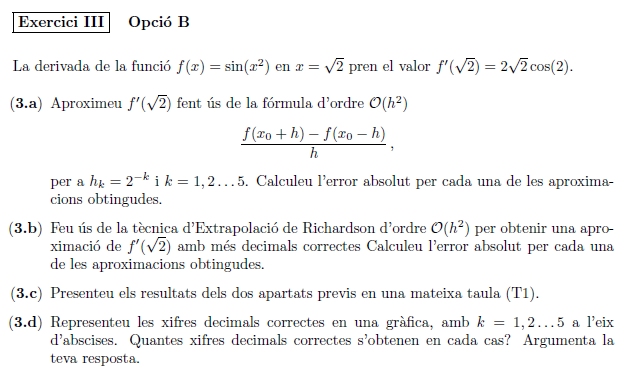

clear all
format shortG

syms t
sym_f(t) = sin(t^2);
sym_df(t) = diff(sym_f(t));

x0 = sqrt(2);
real = double(sym_df(x0));

% Apartado A
f = @(x) sin(x.^2);
df = @(x0,h) (f(x0 + h) - f(x0 - h))/(2*h);

h = 1./(2.^[1:5]);
for k = 1:5
    res(k).h = h(k);
    res(k).value = df(x0,h(k));
    res(k).ea = funerror(res(k).value,real);
end

% Apartado B,C,D
real = double(sym_df(x0));
x0 = sqrt(2);
N_0 = @(h) (f(x0 + h) - f(x0 - h))/(2*h);
N_1 = @(h) N_0(h./2) + (N_0(h./2) - N_0(h))/(-1);
N_2 = @(h) N_1(h./2) + (N_1(h./2) - N_1(h))/((4.^1)-1);
N_3 = @(h) N_2(h./2) + (N_2(h./2) - N_2(h))/((4.^2)-1);
N_4 = @(h) N_3(h./2) + (N_3(h./2) - N_3(h))/((4.^3)-1);

h = 1./(2.^[1:5]);
for k = 1:5
    res1(k,1) = h(k);
    res1(k,2) = N_1(h(k));
    res1(k,3) = funerror(res1(k,2),real);
    decimals_1(k) = correctDec(res1(k,2),real);
end
RES = res1;
res1 = array2table(RES,"VariableNames",{'1/2^k', 'N_1', 'error'});

for k = 0:4
    index = k+1;
    if k > 0
        res2(index,1) = N_2(h(k));
        res2(index,2) = funerror(res2(index,1),real);
        decimals_2(index) = correctDec(res2(index,1),real);
    else
        res2(index,:) = 0;
    end
end
RES = [RES(:,1:end-1) res2];
res2 = array2table(RES,"VariableNames",{'1/2^k', 'N_1', 'N_2', 'error'});

for k = -1:3
    index = k+2;
    if k > 0
        res3(index,1) = N_3(h(k));
        res3(index,2) = funerror(res3(index,1),real);
        decimals_3(index) = correctDec(res3(index,1),real);
    else
        res3(index,:) = 0;
    end
end
RES = [RES(:,1:end-1) res3];
res3 = array2table(RES,"VariableNames",{'1/2^k', 'N_1', 'N_2', 'N_3', 'error'});

for k = -2:2
    index = k+3;
    if k > 0
        res4(index,1) = N_4(h(k));
        res4(index,2) = funerror(res4(index,1),real);
        decimals_4(index) = correctDec(res4(index,1),real);
    else
        res4(index,:) = 0;
    end
end
RES = [RES(:,1:end-1) res4];
res4 = array2table(RES,"VariableNames",{'1/2^k', 'N_1', 'N_2', 'N_3', 'N_4', 'error'});
T1 = array2table(RES,"VariableNames",{'1/2^k', 'N_1', 'N_2', 'N_3', 'N_4', 'error'});

#### RESULTADOS

Apartado A

real, res

real =        -1.177


res = 1×5 struct array with fields:
    h
    value
    ea


Apartado B

res1, res2, res3, res4

res1 = 5×3 table
     1/2^k       N_1        error   
    _______    _______    __________

        0.5     -1.241      0.063936
       0.25    -1.2268      0.049807
      0.125    -1.1919      0.014842
     0.0625    -1.1809     0.0038644
    0.03125     -1.178    0.00097577


res2 = 5×4 table
     1/2^k       N_1        N_2        error   
    _______    _______    _______    __________

        0.5     -1.241          0             0
       0.25    -1.2268    -1.2221      0.045098
      0.125    -1.1919    -1.1802     0.0031876
     0.0625    -1.1809    -1.1772    0.00020499
    0.03125     -1.178    -1.1771    1.2902e-05


res3 = 5×5 table
     1/2^k       N_1        N_2        N_3        error   
    _______    _______    _______    _______    __________

        0.5     -1.241          0          0             0
       0.25    -1.2268    -1.2221          0             0
      0.125    -1.1919    -1.1802    -1.1774    0.00039356
     0.0625    -1.1809    -1.1772     -1.177    6.1492e-06
    0.03125     -1.178    -1.1771     -1.177    9.5921e-08


res4 = 5×6 table
     1/2^k       N_1        N_2        N_3       N_4        error   
    _______    _______    _______    _______    ______    __________

        0.5     -1.241          0          0         0             0
       0.25    -1.2268    -1.2221          0         0             0
      0.125    -1.1919    -1.1802    -1.1774         0             0
     0.0625    -1.1809    -1.1772     -1.177    -1.177    1.7092e-10
    0.03125     -1.178    -1.1771     -1.177    -1.177    1.6223e-10


Apartado C

T1

T1 = 5×6 table
     1/2^k       N_1        N_2        N_3       N_4        error   
    _______    _______    _______    _______    ______    __________

        0.5     -1.241          0          0         0             0
       0.25    -1.2268    -1.2221          0         0             0
      0.125    -1.1919    -1.1802    -1.1774         0             0
     0.0625    -1.1809    -1.1772     -1.177    -1.177    1.7092e-10
    0.03125     -1.178    -1.1771     -1.177    -1.177    1.6223e-10


Apartado D

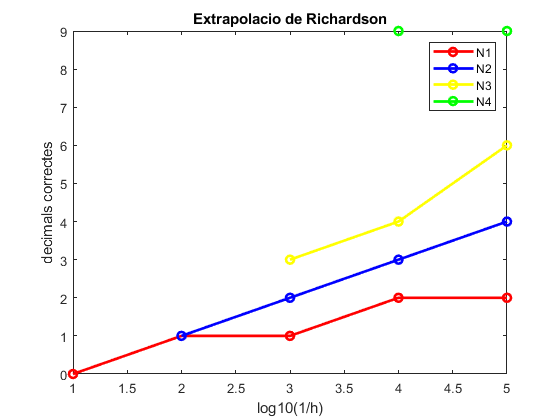

plot([1:5], decimals_1, 'r-o', ...
    [2:5], decimals_2(2:end), 'b-o', ...
    [3:5], decimals_3(3:end), 'y-o', ...
    [4:5], decimals_4(5:end), 'g-o', ...
    'LineWidth', 2);


legend('N1','N2','N3','N4');
title("Extrapolacio de Richardson");
xlabel("log10(1/h)");
ylabel("decimals correctes");